# Part 1

## Up conversion and down conversion without noise

%provided files:
%Sym_TX：32 modulated symbols using 16-QAM with average power 1
%Sig_BB_TX_Upsamp：up-sampled signal in the baseband with sampling rate 1000 Hz
%tSamp：sampling time for Sig_BB_TX_Upsamp

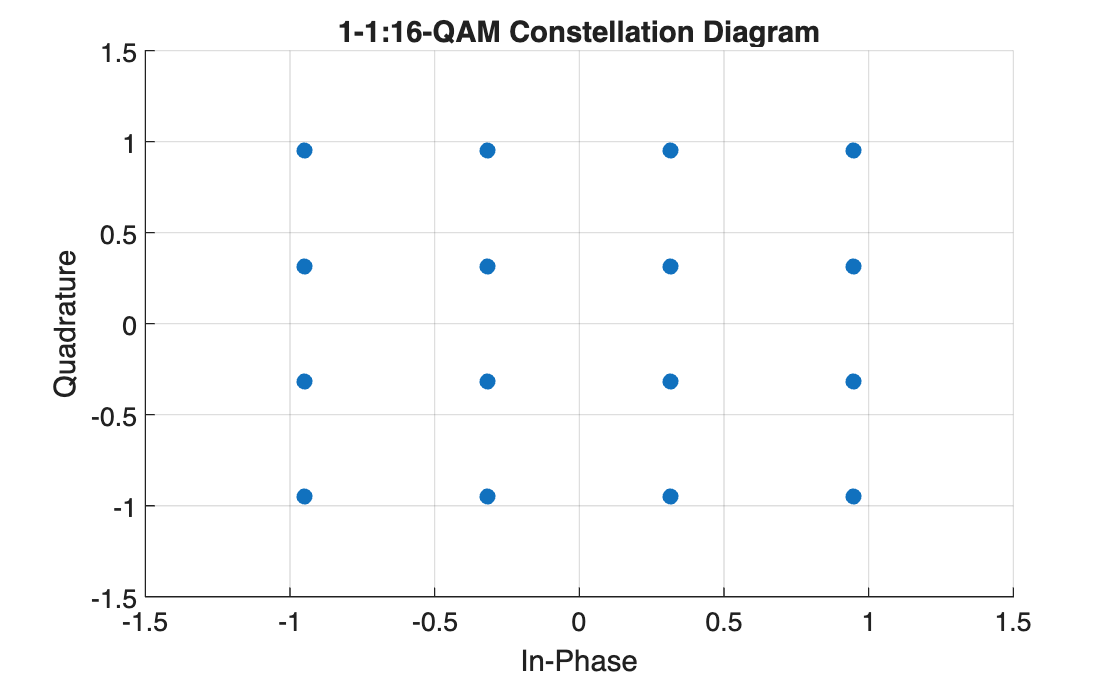

%1:
figure;
scatter(real(Sym_TX), imag(Sym_TX), 'filled');
xlabel('In-Phase');
ylabel('Quadrature');
title('1-1:16-QAM Constellation Diagram');
grid on;
axis([-1.5 1.5 -1.5 1.5]);

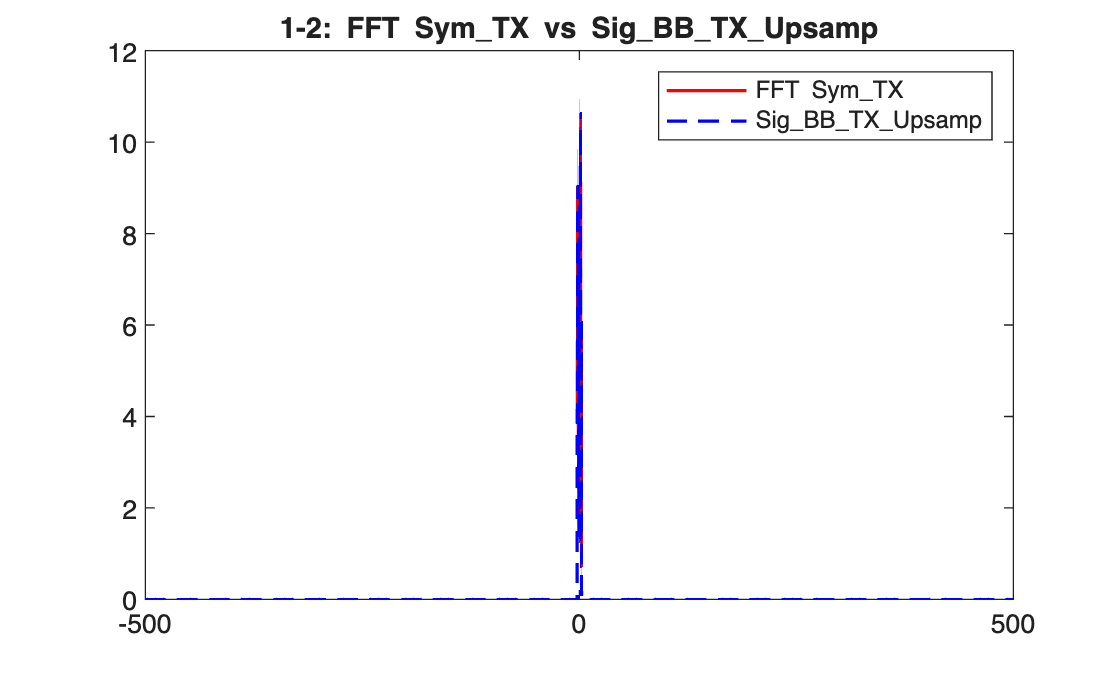

%2: 
% Perform FFT on Sym_TX
N_symbols = length(Sym_TX);%32
symbol_rate = 5; % Hz (5 symbols per second)
freq_sym = linspace(-symbol_rate/2, symbol_rate/2, N_symbols);
Sym_TX_fft = fftshift(fft(Sym_TX));

% Perform FFT on Sig_BB_TX_Upsamp
N_samples = length(Sig_BB_TX_Upsamp);%6400
Sampling_rate = 1000; % Hz (5 symbols per second)
freq_BB = linspace(-Sampling_rate/2, Sampling_rate/2, N_samples);
BB_fft = fftshift(fft(Sig_BB_TX_Upsamp));

% plot
figure;
plot(freq_sym, abs(Sym_TX_fft), 'r', 'LineWidth', 1.2);
hold on;
plot(freq_BB, 1/200*abs(BB_fft),  'b--', 'LineWidth', 1.2);
title('1-2: FFT Sym\_TX vs Sig\_BB\_TX\_Upsamp');
legend('FFT Sym\_TX', 'Sig\_BB\_TX\_Upsamp');
xlim([-500 500])

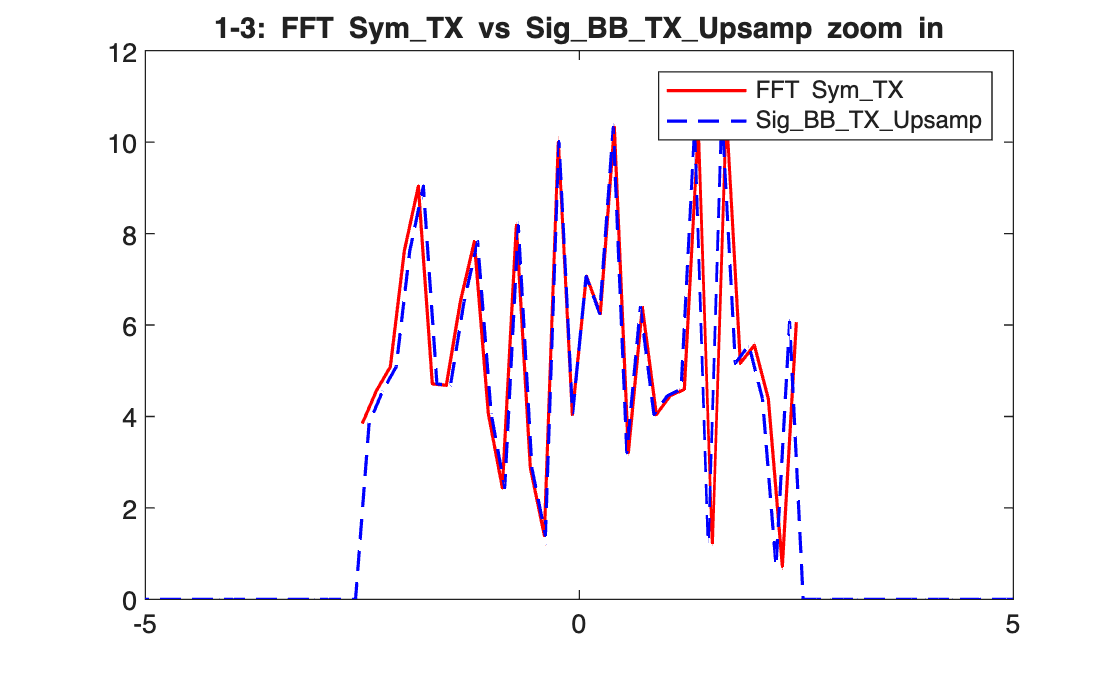

%3: 
figure;
plot(freq_sym, abs(Sym_TX_fft), 'r', 'LineWidth', 1.2);
hold on;
plot(freq_BB, 1/200*abs(BB_fft),  'b--', 'LineWidth', 1.2);
title('1-3: FFT Sym\_TX vs Sig\_BB\_TX\_Upsamp zoom in');
legend('FFT Sym\_TX', 'Sig\_BB\_TX\_Upsamp');
xlim([-5 5])

fprintf("the bandwidth is about 5 Hz.")

the bandwidth is about 5 Hz.

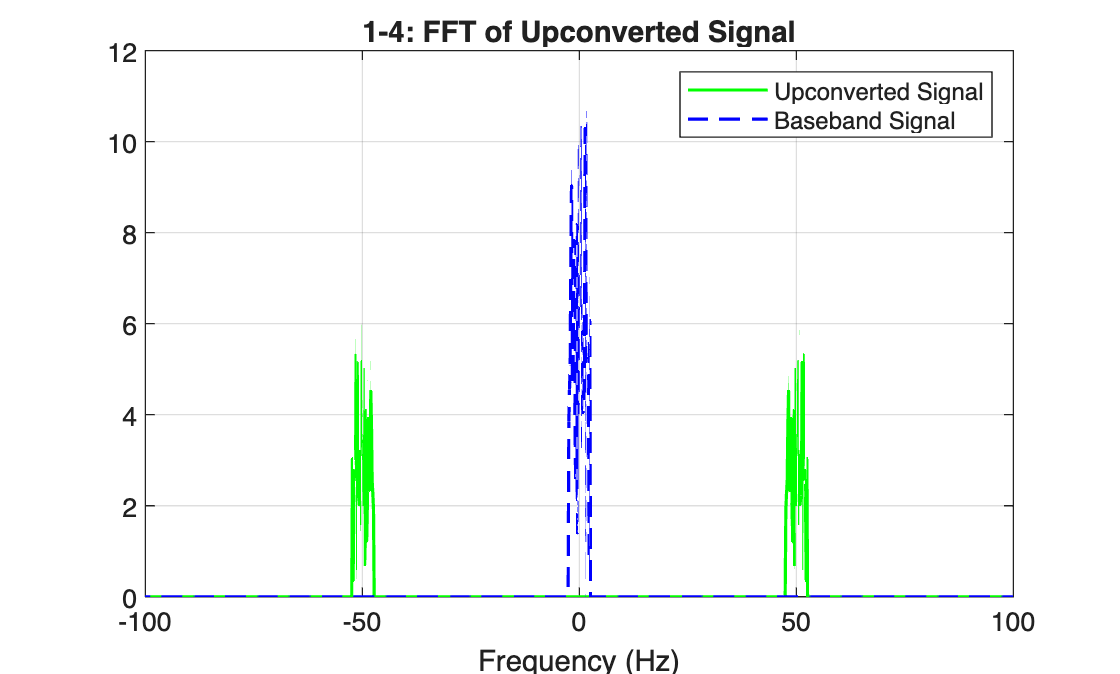

%4: 
fc = 50;
t = tSamp(:);
X_up_convert = real(Sig_BB_TX_Upsamp(:).*exp(1j*2*pi*fc*t));
X_up_convert_fft = fftshift(fft(X_up_convert));
freq_up_convert = linspace(-Sampling_rate/2, Sampling_rate/2, length(X_up_convert_fft));

%plot
figure;
plot(freq_up_convert, 1/200*abs(X_up_convert_fft), 'g', 'LineWidth', 1.2);
hold on;
plot(freq_BB, 1/200*abs(BB_fft), 'b--', 'LineWidth', 1.2);
title('1-4: FFT of Upconverted Signal');
xlabel('Frequency (Hz)');
legend('Upconverted Signal', 'Baseband Signal');
xlim([-100 100]);
grid on;

fprintf("1-4: upconverted signal center around +-50 Hz.")

1-4: upconverted signal center around +-50 Hz.

%5:
Nshow = 8*N_samples/N_symbols

Nshow = 1600

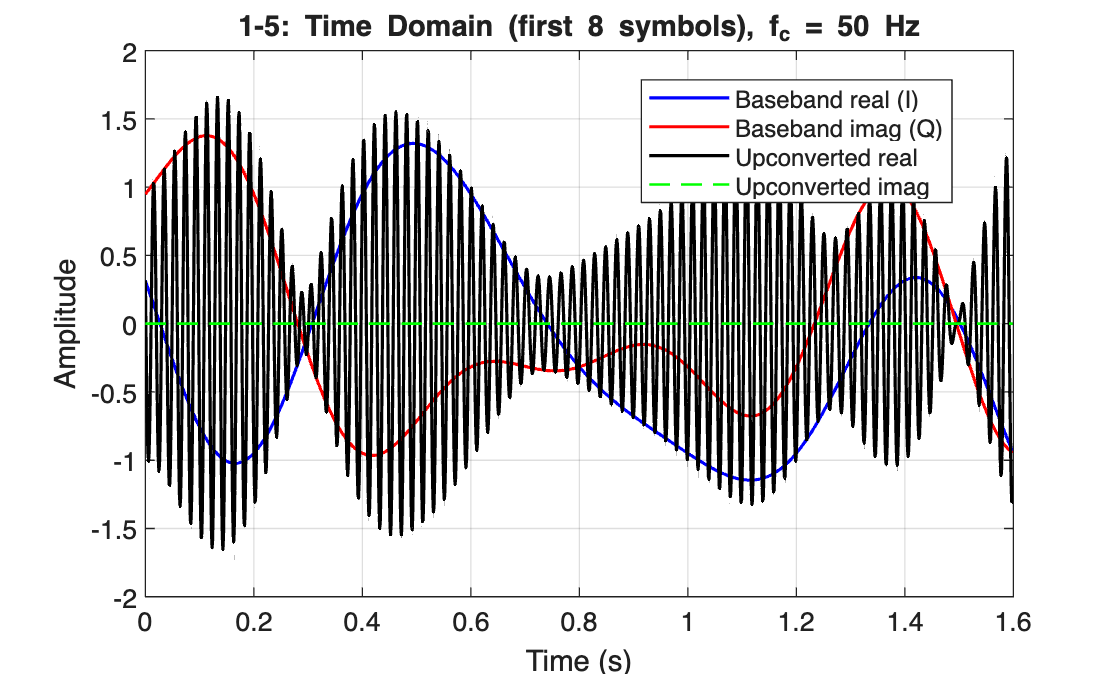

figure;
plot(t(1:Nshow), real(Sig_BB_TX_Upsamp(1:Nshow)), 'b-', 'LineWidth', 1.2); hold on;
plot(t(1:Nshow), imag(Sig_BB_TX_Upsamp(1:Nshow)), 'r-', 'LineWidth', 1.2);
plot(t(1:Nshow), real(X_up_convert(1:Nshow)),  'k-', 'LineWidth', 1.2);
plot(t(1:Nshow), imag(X_up_convert(1:Nshow)), 'g--', 'LineWidth', 1.0);
grid on; 
xlabel('Time (s)'); ylabel('Amplitude');
title(sprintf('1-5: Time Domain (first 8 symbols), f_c = %g Hz', fc));
legend('Baseband real (I)', 'Baseband imag (Q)', ...
       'Upconverted real', 'Upconverted imag', ...
       'Location','best');

fprintf("1-5: Although the base band is complex, the transmitting signal is still real")

1-5: Although the base band is complex, the transmitting signal is still real

%6:
fprintf("1-6: According to the Nyquist rate, the minimum cutoff frequency is \n" + ...
    "    0.5*samplingrate = 2.5Hz.")

1-6: According to the Nyquist rate, the minimum cutoff frequency is 
    0.5*samplingrate = 2.5Hz.

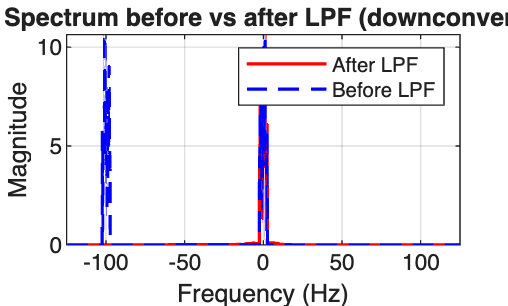

%7:
% down conversion
X_down_convert = 2 * X_up_convert.*exp(-1j*2*pi*fc*t);
fpass = 2.5;  
X_down_convert_lpf = lowpass(X_down_convert, fpass, Sampling_rate, 'Steepness', 0.99);
X_down_convert_fft = fftshift(fft(X_down_convert));
X_down_convert_lpf_fft = fftshift(fft(X_down_convert_lpf)); 
freq_down_convert = linspace(-Sampling_rate/2, Sampling_rate/2,length(X_down_convert_fft));

% plot
figure;
plot(freq_down_convert, 1/200*abs(X_down_convert_lpf_fft), 'r', 'LineWidth', 1.2);
hold on;
plot(freq_down_convert, 1/200*abs(X_down_convert_fft), 'b--', 'LineWidth', 1.2);
xlim([-125 125]); 
grid on;
xlabel('Frequency (Hz)'); ylabel('Magnitude');
title('1-7: Spectrum before vs after LPF (downconversion)');
legend('After LPF','Before LPF');

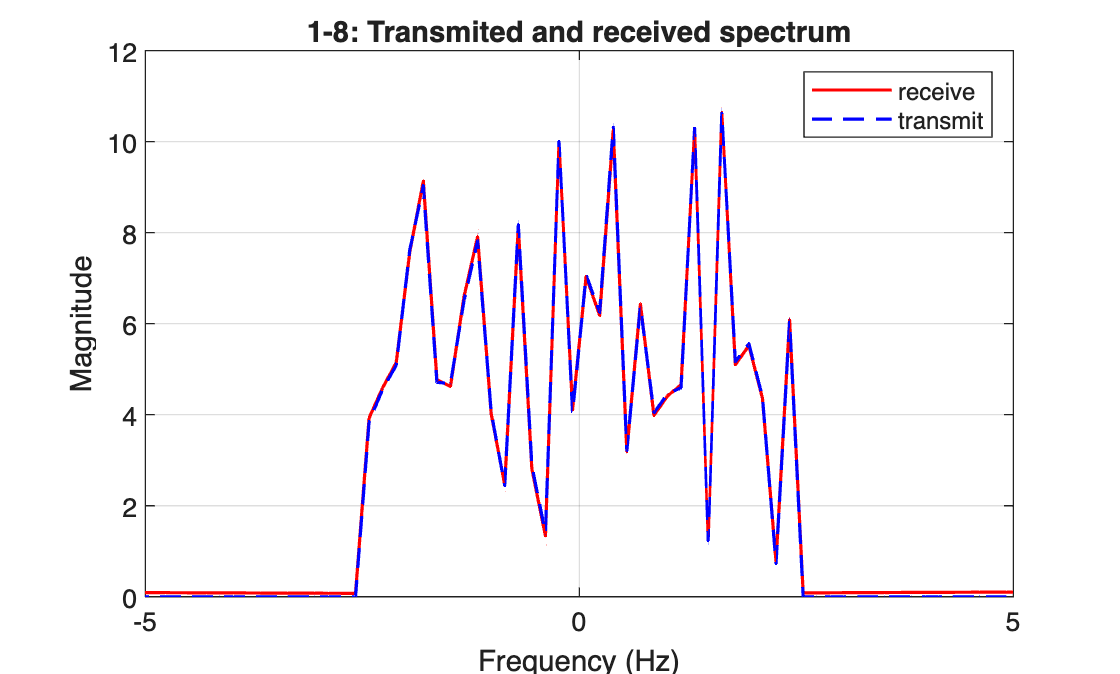

%8:
figure;
plot(freq_down_convert, 1/200*abs(X_down_convert_lpf_fft), 'r', 'LineWidth', 1.2);
hold on;
plot(freq_BB, 1/200*abs(BB_fft),  'b--', 'LineWidth', 1.2);
xlim([-5 5]);
grid on;
xlabel('Frequency (Hz)'); ylabel('Magnitude');
title('1-8: Transmited and received spectrum');
legend('receive','transmit');

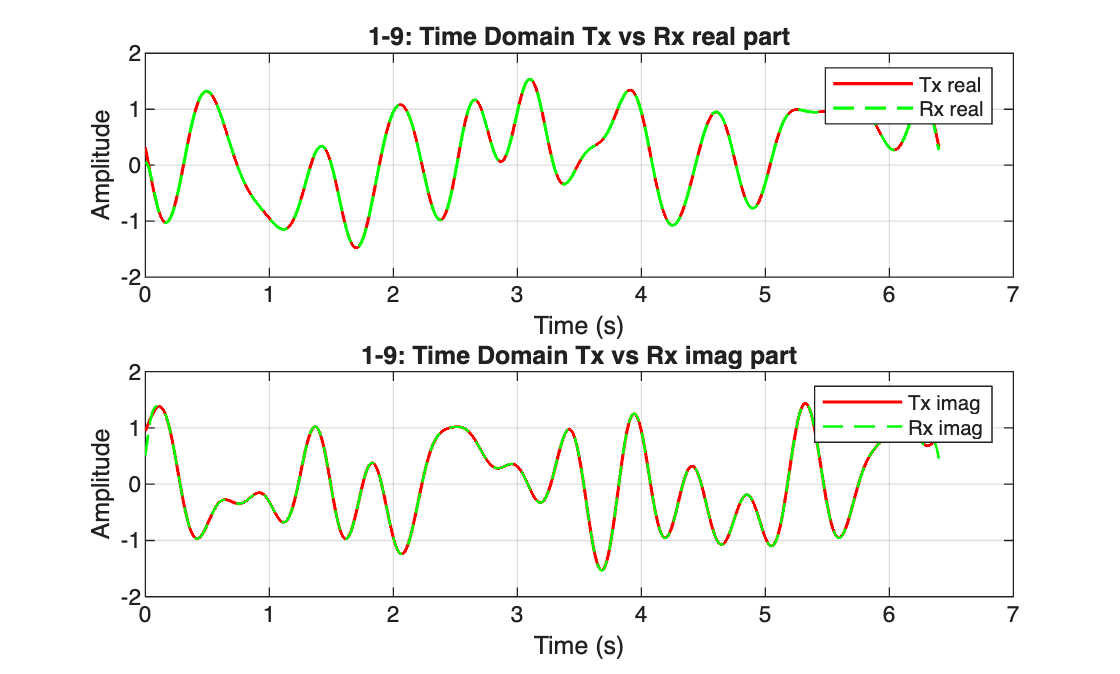

%9:
Nshow = 8*N_samples/N_symbols;
figure;
subplot(2,1,1);
plot(tSamp, real(Sig_BB_TX_Upsamp), 'r-', 'LineWidth', 1.2); 
hold on;
plot(tSamp, real(X_down_convert_lpf),  'g--', 'LineWidth', 1.2);
grid on;
xlabel('Time (s)'); ylabel('Amplitude');
title(sprintf('1-9: Time Domain Tx vs Rx real part'));
legend('Tx real','Rx real');

subplot(2,1,2)
plot(tSamp, imag(Sig_BB_TX_Upsamp), 'r-', 'LineWidth', 1.2);
hold on;
plot(tSamp, imag(X_down_convert_lpf), 'g--', 'LineWidth', 1.0);
grid on; 
xlabel('Time (s)'); ylabel('Amplitude');
title(sprintf('1-9: Time Domain Tx vs Rx imag part'));
legend('Tx imag','Rx imag');

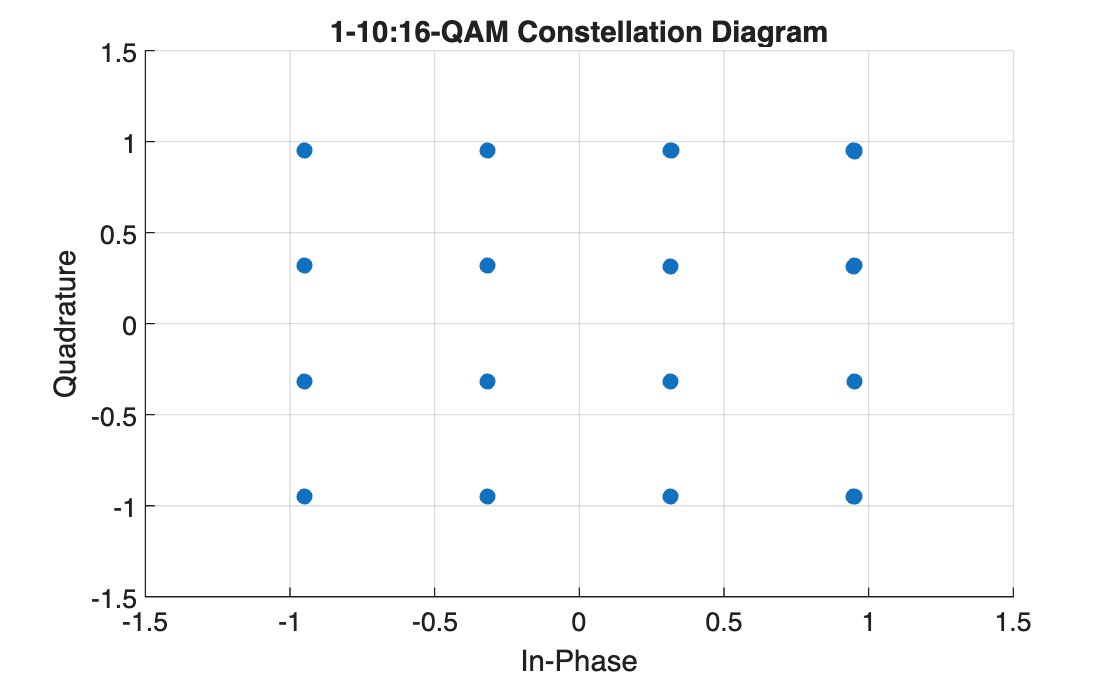

%10:
figure;
y = X_down_convert_lpf(1:200:end);
scatter(real(y(2:end)), imag(y(2:end)), 'filled');
xlabel('In-Phase');
ylabel('Quadrature');
title('1-10:16-QAM Constellation Diagram');
grid on;
axis([-1.5 1.5 -1.5 1.5]);

%the first sample is polluted by the transient state of LPF, thus discarded

## Additive noise

%11:
P_Sym = mean(abs(Sym_TX).^2);
P_BB  = mean(abs(Sig_BB_TX_Upsamp).^2);

fprintf('1-11: Power of Sym_TX            = %.6f\n', P_Sym);

1-11: Power of Sym_TX            = 1.175000


fprintf('1-11: Power of Sig_BB_TX_Upsamp  = %.6f\n', P_BB);

1-11: Power of Sig_BB_TX_Upsamp  = 1.175000


`The main reason is the limited number of symbols, if each symbol does not occur evenly, `

`the power will be slightly different to the expected value.`


$$$I, Q \in \{\pm 1, \pm 3\}$ 
with equal probability.

The expected squared value of one component is
\[
\mathbb{E}[I^2] = \mathbb{E}[Q^2] 
= \frac{1^2 + 1^2 + 3^2 + 3^2}{4} = 5.
\]

Thus, the expected symbol energy is
\[
\mathbb{E}[|S|^2] = \mathbb{E}[I^2 + Q^2] = 5 + 5 = 10.
\]

By scaling the constellation by $\frac{1}{\sqrt{10}}$, the normalized 
symbol energy is
\[
\mathbb{E}\!\left[ \left| \frac{S}{\sqrt{10}} \right|^2 \right] 
= \frac{1}{10} \cdot \mathbb{E}[|S|^2] 
= \frac{1}{10} \cdot 10 = 1.
\]$$


%12:

If $\textrm{SNR}=\;20\textrm{db}=100=\frac{Ｐ_{\textrm{signal}} }{P_{\textrm{noise}} }$, $P_{\textrm{noise}} =\frac{1\ldotp 175}{100}=0\ldotp 01175\ldotp$

%13:

Assume that additive white Gaussian noise (AWGN) at RF has variance $$\sigma^2$,$i.e., the average noise power per sample is $\[
P_{\text{noise,RF}} = \sigma^2.
\]$

After downconversion and lowpass filtering, the noise power changes because of two factors:

First,  the downconversion multiplie scales the signal amplitude by 2, hence scales the power by $2^2$ = 4.

Second, the lowpass filter only keeps noise within bandwidth 2B compared to the full bandwidth $F_s$ . Thus the fraction of noise 

retained is $\frac{2B}{F_s }$.

Therefore, the average noise power at baseband is$P_{\text{noise,BB}}
= 4 \, \sigma^2 \cdot \frac{2B}{F_s}
= \sigma^2 \cdot \frac{8B}{F_s}
= 0.02\sigma^2.$

%14:


$$P_{\text{noise,BB}}
= \sigma^2 \cdot \frac{8 \times 2.5}{1000}
= \sigma^2 \cdot 0.02.
=0.01175
$$


$\sigma =\sqrt{0\ldotp 5875}$.

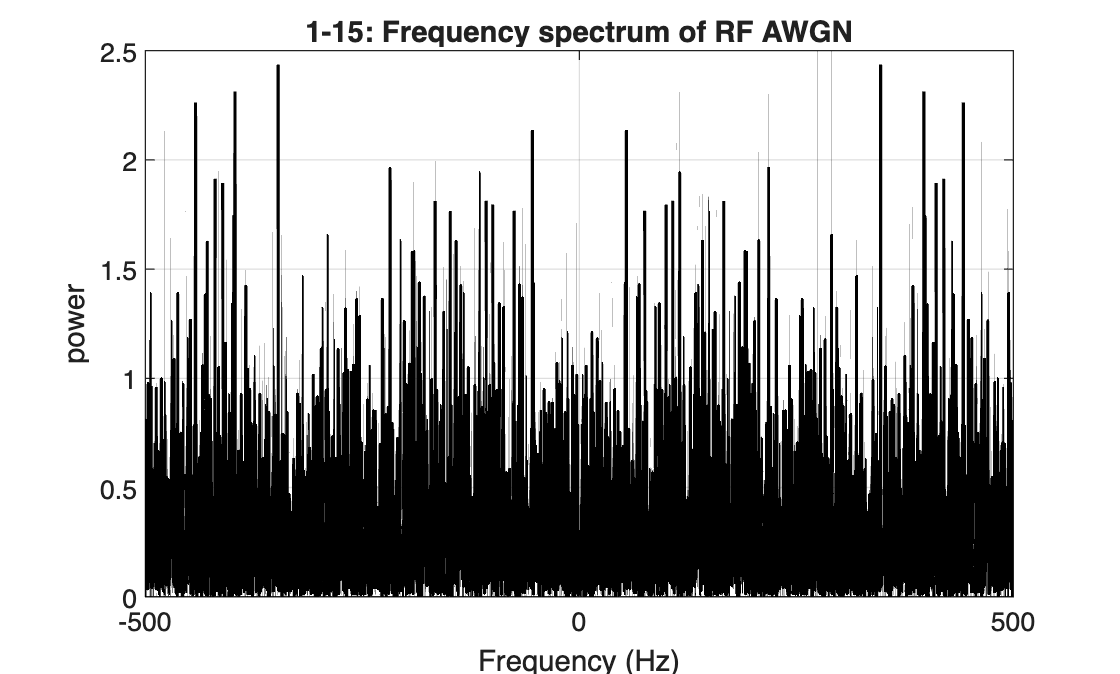

%15:
B        = 2.5;
PnoiseBB = 0.01;
sigma2   = 0.5875;
sigma    = sqrt(sigma2);
%noise generation
rng(42);
n_rf = sigma/sqrt(2) * randn(N_samples,1);% AWGN with var = sigma^2
Fpower = fftshift(fft(n_rf)).^2/N_samples;

%plot
figure;
plot(freq_BB, abs(Fpower), 'k', 'LineWidth', 1.2);
xlim([-500 500]); 
grid on;
xlabel('Frequency (Hz)'); ylabel('power');
title('1-15: Frequency spectrum of RF AWGN');

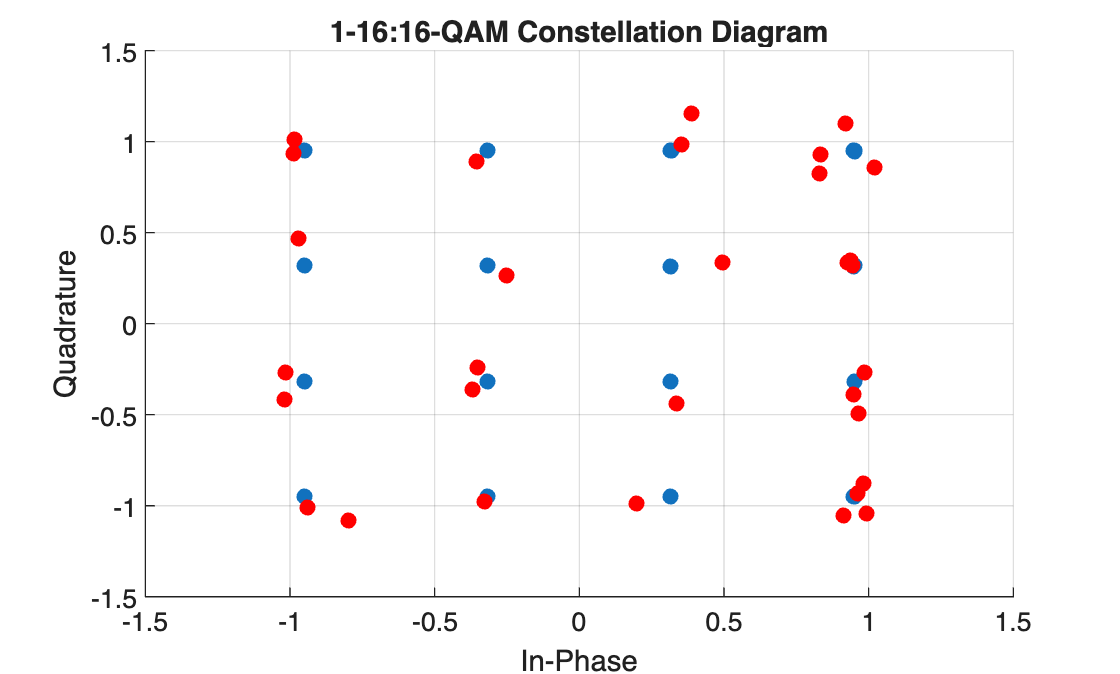

%16
x_rf_noisy = X_up_convert + n_rf;
X_down_noisy = 2 * x_rf_noisy .* exp(-1j*2*pi*fc*t);
X_down_noisy_lpf = lowpass(X_down_noisy, fpass, Sampling_rate, 'Steepness', 0.99);
y_noisy = decimate(X_down_noisy_lpf, 200, 'fir');%downsampling
%plot
%noiseless
figure;
scatter(real(y(2:end)), imag(y(2:end)), 'filled');
hold on;
scatter(real(y_noisy(2:end)), imag(y_noisy(2:end)),'r', 'filled');
xlabel('In-Phase');
ylabel('Quadrature');
title('1-16:16-QAM Constellation Diagram');
grid on;
axis([-1.5 1.5 -1.5 1.5]);

%17
error = y_noisy(2:end) - y(2:end);
P_noise = mean(abs(error).^2);
SNR_all_dB  = 10*log10(P_Sym/P_noise);%problem 11

fprintf('1-17: Empirical noise power = %.5f\n', P_noise);

1-17: Empirical noise power = 0.01233


fprintf('1-17: Empirical SNR = %.2f dB\n', SNR_all_dB);

1-17: Empirical SNR = 19.79 dB


# Part2

## Gray code vs natural code

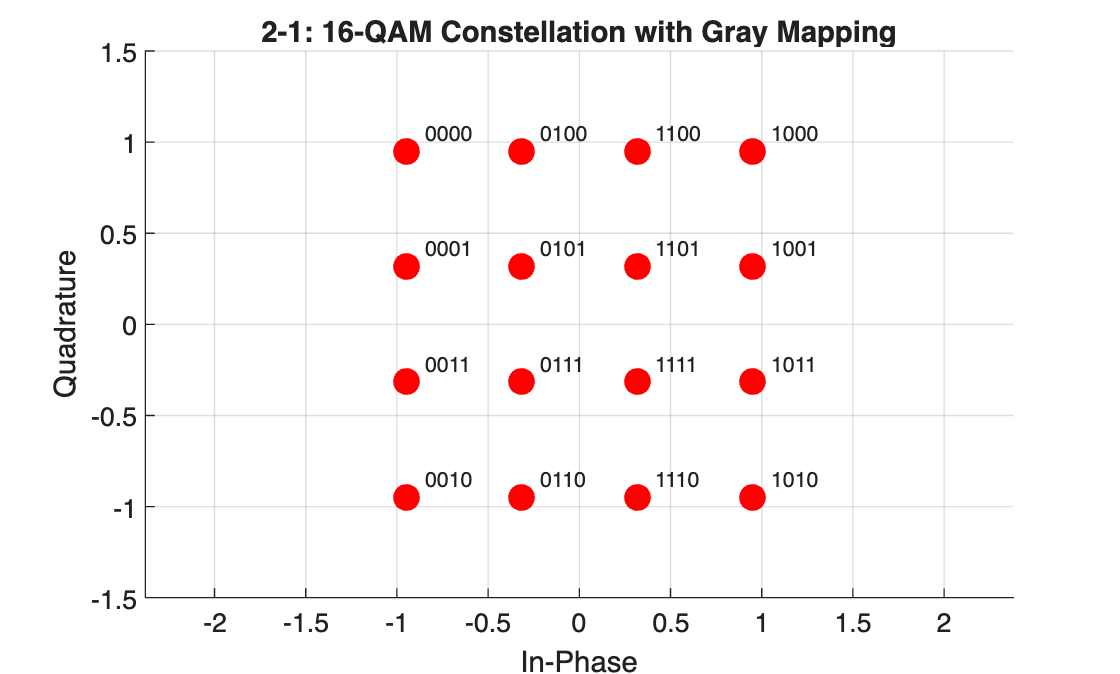

%1
% Parameters
SNR_dB = 10;
SNR_linear = 10^(SNR_dB/10);  
num_bits = 10^6;              
bits_per_symbol = 4;          
num_symbols = num_bits / bits_per_symbol;%250000

% Generate random bits
rng(42);  
tx_bits = randi([0 1], num_bits, 1);

% Modulate with 16-QAM using Gray coding
% MATLAB's qammod uses Gray mapping by default
tx_symbols_gray = qammod(tx_bits, 16, 'InputType', 'bit','UnitAveragePower', true);

% Calculate signal power (should be 1 due to UnitAveragePower = true)
signal_power = mean(abs(tx_symbols_gray).^2);

% Calculate noise variance for desired SNR
noise_variance = signal_power / SNR_linear;

% Generate complex AWGN
noise = sqrt(noise_variance/2) * (randn(num_symbols, 1) + 1j*randn(num_symbols, 1));

% Add noise to symbols
rx_symbols_gray = tx_symbols_gray + noise;

% Plot constellation with Gray mapping
figure;
constellation_points = qammod(0:15, 16, 'UnitAveragePower', true);
scatter(real(constellation_points), imag(constellation_points), 100, 'filled', 'r');
hold on;
for i = 0:15
    gray_bits = de2bi(i, 4, 'left-msb');  % Convert to 4-bit Gray code
    text(real(constellation_points(i+1))+0.1, imag(constellation_points(i+1))+0.1, ...
         sprintf('%d%d%d%d', gray_bits), 'FontSize', 8);
end
grid on;
xlabel('In-Phase');
ylabel('Quadrature');
title('2-1: 16-QAM Constellation with Gray Mapping');
xlim([-1.5 1.5])
ylim([-1.5 1.5])
axis equal;

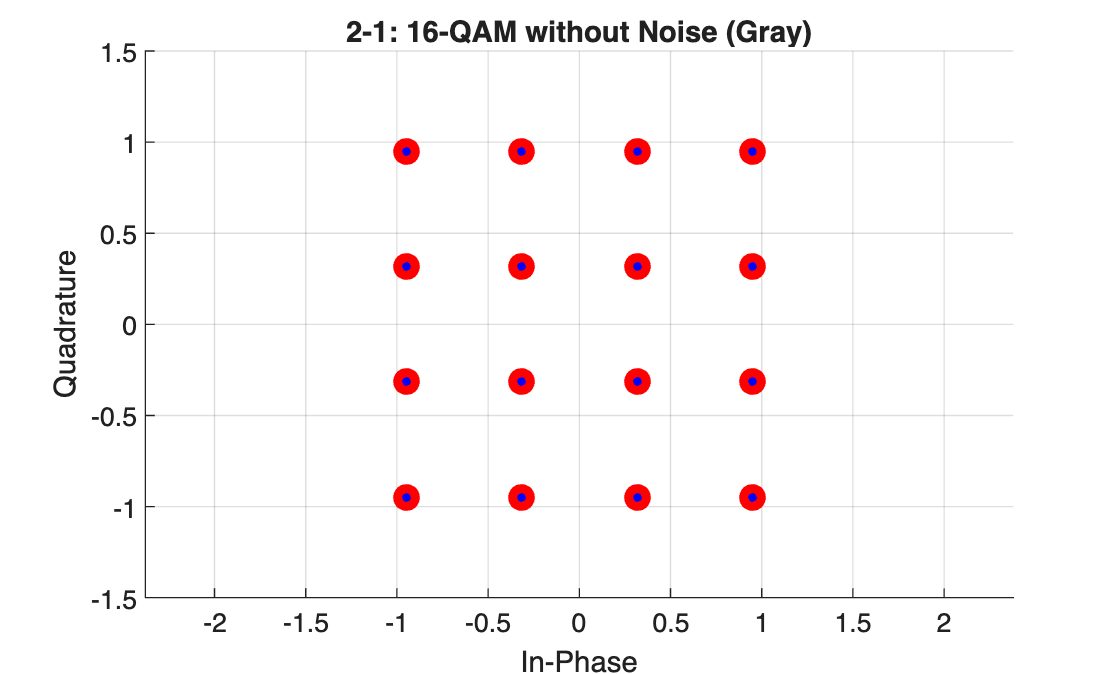


% Plot trasmitting constellation
figure;
scatter(real(constellation_points), imag(constellation_points),100, 'filled', 'r');
hold on;
scatter(real(tx_symbols_gray), imag(tx_symbols_gray), 10, 'b', 'filled', 'MarkerFaceAlpha', 0.3);
grid on;
xlabel('In-Phase');
ylabel('Quadrature');
title('2-1: 16-QAM without Noise (Gray)');
xlim([-1.5 1.5])
ylim([-1.5 1.5])
axis equal;

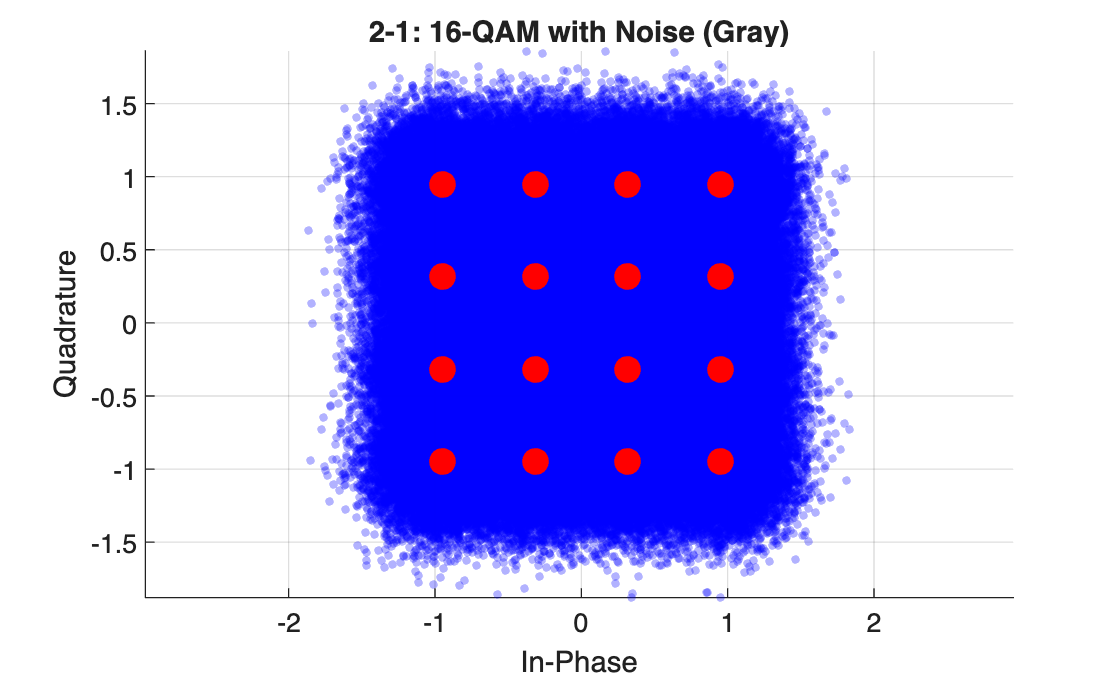


figure;
scatter(real(rx_symbols_gray), imag(rx_symbols_gray), 10, 'b', 'filled', 'MarkerFaceAlpha', 0.3);
hold on;
scatter(real(constellation_points), imag(constellation_points),100, 'filled', 'r');
grid on;
xlabel('In-Phase');
ylabel('Quadrature');
title('2-1: 16-QAM with Noise (Gray)');
xlim([-1.5 1.5])
axis equal;

%2:
empirical_signal_power = signal_power;
empirical_noise_power = mean(abs(noise).^2);
empirical_SNR_dB = 10*log10(empirical_signal_power / empirical_noise_power);

fprintf('2-2(a): Empirical signal power: %.6f\n', empirical_signal_power);

2-2(a): Empirical signal power: 0.999008


fprintf('2-2(b): Empirical noise power: %.6f\n', empirical_noise_power);

2-2(b): Empirical noise power: 0.100002


fprintf('2-2(c): Empirical SNR: %.2f dB\n', empirical_SNR_dB);

2-2(c): Empirical SNR: 10.00 dB


%3:
rx_bits_gray = qamdemod(rx_symbols_gray, 16, 'OutputType', 'bit','UnitAveragePower', true);

% Calculate bit error rate
bit_errors_gray = sum(tx_bits ~= rx_bits_gray);
BER_gray = bit_errors_gray / num_bits;
fprintf('2-3: Bit Error Rate (Gray coding): %.6f\n', BER_gray);

2-3: Bit Error Rate (Gray coding): 0.059239


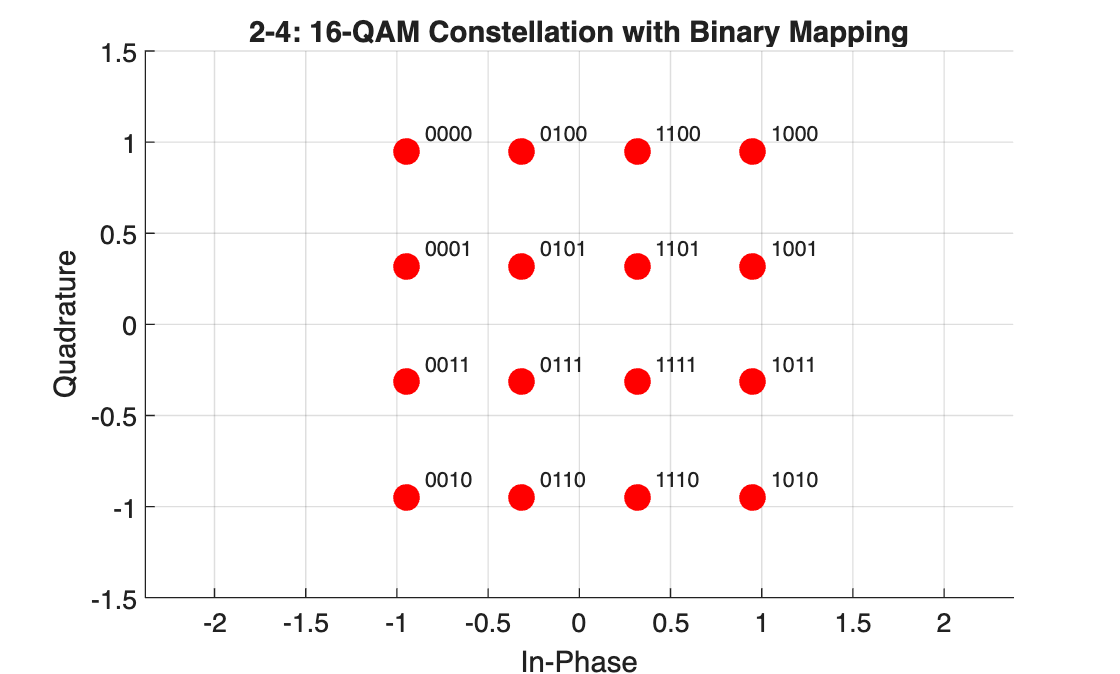

%4:
% Generate the same random bits for fair comparison
tx_symbols_binary = qammod(tx_bits, 16,'bin', 'InputType','bit');
Pb = mean(abs(tx_symbols_binary).^2);
tx_symbols_binary = tx_symbols_binary / sqrt(Pb);
% Add the same noise power
noise_binary = sqrt(noise_variance/2) * (randn(num_symbols, 1) + 1j*randn(num_symbols, 1));
rx_symbols_binary = tx_symbols_binary + noise_binary;

% Plot constellation with Binary mapping
figure;
constellation_points_binary = qammod(0:15, 16, 'UnitAveragePower', true);
scatter(real(constellation_points_binary), imag(constellation_points_binary), 100, 'filled', 'r');
hold on;
for i = 0:15
    binary_bits = de2bi(i, 4, 'left-msb');  % Convert to 4-bit binary
    text(real(constellation_points_binary(i+1))+0.1, imag(constellation_points_binary(i+1))+0.1, ...
         sprintf('%d%d%d%d', binary_bits), 'FontSize', 8);
end
grid on;
xlabel('In-Phase');
ylabel('Quadrature');
title('2-4: 16-QAM Constellation with Binary Mapping');
ylim([-1.5 1.5])
axis equal;

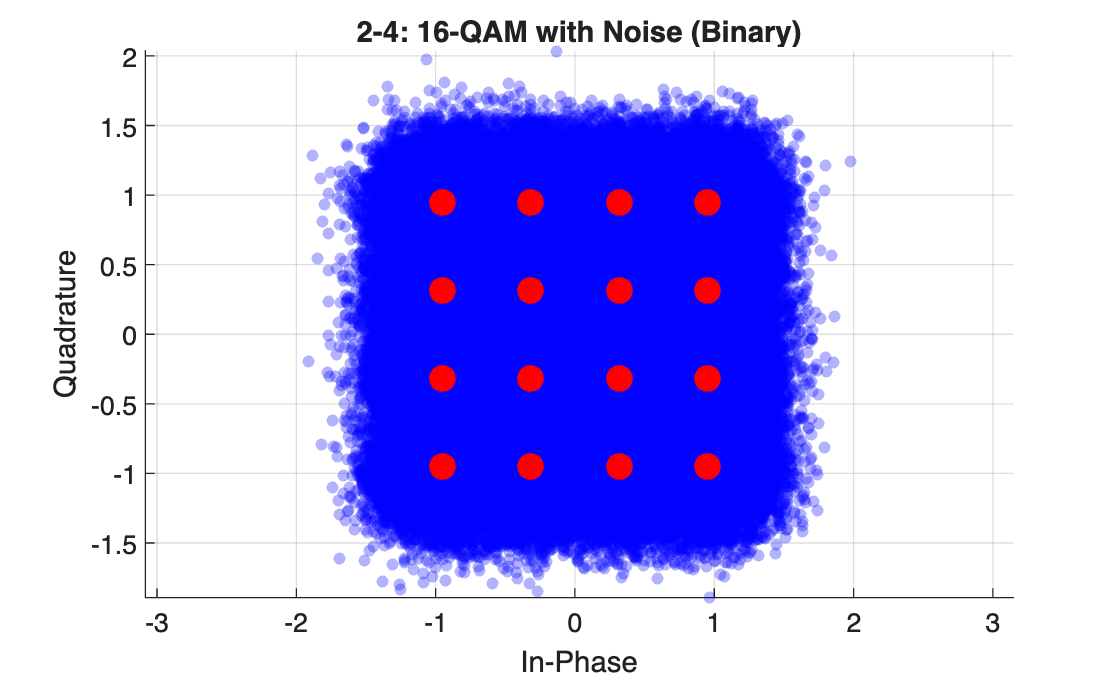


% Plot received constellation
figure;
scatter(real(rx_symbols_binary), imag(rx_symbols_binary), 20, 'b', 'filled', 'MarkerFaceAlpha', 0.3);
hold on;
scatter(real(constellation_points_binary), imag(constellation_points_binary), 100, 'filled', 'r');
grid on;
xlabel('In-Phase');
ylabel('Quadrature');
title('2-4: 16-QAM with Noise (Binary)');
axis equal;

%5:
% Demodulate received symbols with binary mapping
rx_bits_binary = qamdemod(rx_symbols_binary, 16,'bin', 'OutputType','bit');

% Calculate bit error rate
bit_errors_binary = sum(tx_bits ~= rx_bits_binary);
BER_binary = bit_errors_binary / num_bits;

fprintf('2-5: Bit Error Rate (Binary coding): %.6f\n', BER_binary);

2-5: Bit Error Rate (Binary coding): 0.288868


%6:

`Reason for the difference: Gray coding minimizes bit errors because adjacent constellation points differ by only one bit. When a symbol is decoded incorrectly due to noise, it is most likely to be decoded as an adjacent symbol, resulting in only a single bit error. In contrast, binary coding can result in multiple bit errors when a symbol is misinterpreted as an adjacent constellation point, because adjacent points may differ in multiple bit positions. This is why Gray coding typically provides better BER performance than binary coding in AWGN channels.`

## Optimal decoding with MAP

%7:
prob_bit0 = 0.1;  % P(bit = 0) = 0.1
prob_bit1 = 0.9;  % P(bit = 1) = 0.9

% Generate bits with unequal probabilities
rng(42);  % For reproducibility
random_uniform = rand(num_bits, 1);
tx_bits_unequal = zeros(num_bits, 1);
tx_bits_unequal(random_uniform > prob_bit0) = 1;  % bit = 1 when rand > 0.1

% Calculate actual percentage of bit 0
num_zeros = sum(tx_bits_unequal == 0);
percentage_bit0 = (num_zeros / num_bits) * 100;

fprintf('2-7: Percentage of bit 0 in generated sequence: %.2f%%\n', percentage_bit0);

2-7: Percentage of bit 0 in generated sequence: 9.98%


`Strategy for generating unequal probability bits: If random_number <= 0.1, assign bit = 0. If random_number > 0.1, assign bit = 1. This ensures P(bit=0) = 0.1 and P(bit=1) = 0.9.`

%8:
SNR_dB_2 = 5;
SNR_linear_2 = 10^(SNR_dB_2/10);  % Convert 5 dB to linear scale

% For BPSK with unit average power: symbols are +1 and -1
signal_power_expected = 1;

% Calculate required noise variance
noise_variance_bpsk = signal_power_expected / SNR_linear_2;
fprintf('2-8: Required noise variance = %.6f\n', noise_variance_bpsk);

2-8: Required noise variance = 0.316228


%9:
% Map bits to BPSK symbols: 0 -> -1, 1 -> +1
tx_symbols_bpsk = 2*tx_bits_unequal - 1;  % Convert {0,1} to {-1,+1}

% Calculate actual signal power
bpsk_signal_power = mean(tx_symbols_bpsk.^2);

% Generate complex AWGN noise
noise_bpsk = sqrt(noise_variance_bpsk/2) * (randn(num_bits, 1) + 1j*randn(num_bits, 1));

% Add noise to symbols
rx_symbols_bpsk = tx_symbols_bpsk + noise_bpsk;

% Calculate empirical noise power and SNR
empirical_noise_power_bpsk = mean(abs(noise_bpsk).^2);
empirical_SNR_bpsk = 10*log10(bpsk_signal_power / empirical_noise_power_bpsk);

fprintf('2-9: Empirical SNR: %.2f dB\n', empirical_SNR_bpsk);

2-9: Empirical SNR: 5.01 dB


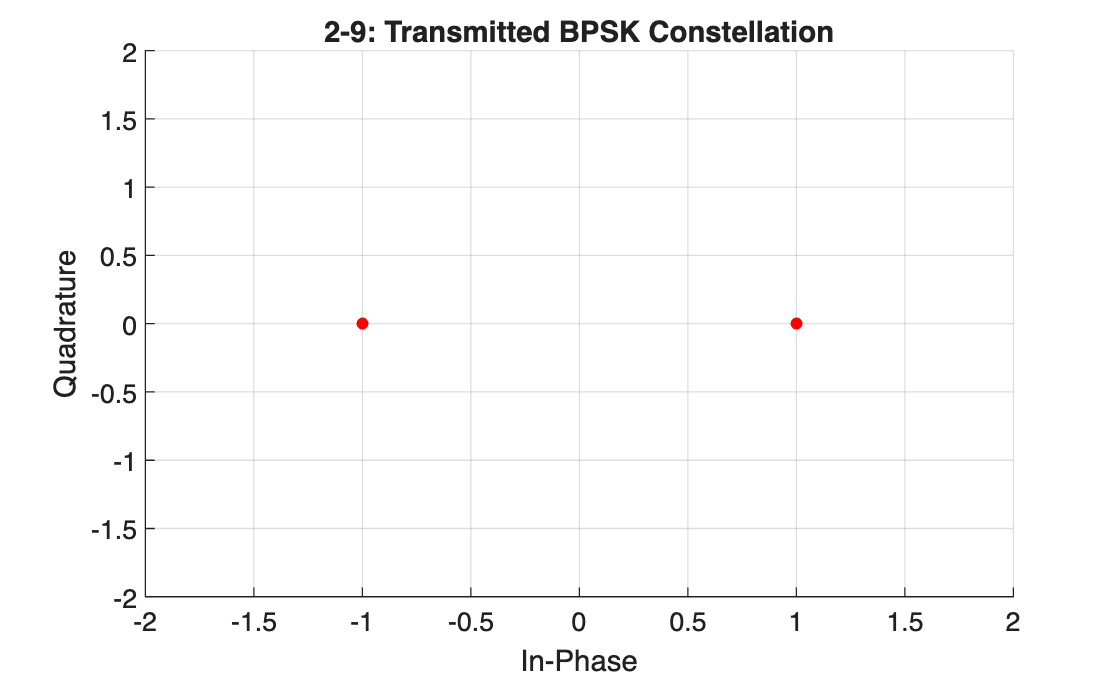


% Plot constellation
figure;
scatter(real(tx_symbols_bpsk(1:1000)), imag(tx_symbols_bpsk(1:1000)), 20, 'r', 'filled');
xlabel('In-Phase');
ylabel('Quadrature');
title('2-9: Transmitted BPSK Constellation');
grid on;
axis([-2 2 -2 2]);

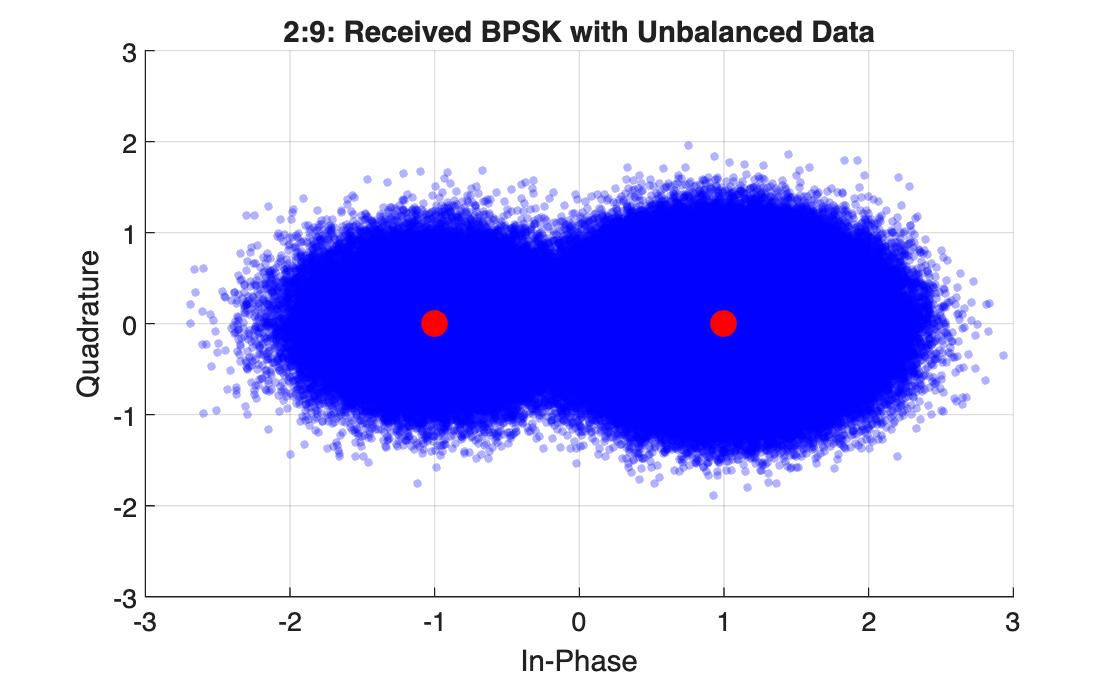


figure;
scatter(real(rx_symbols_bpsk), imag(rx_symbols_bpsk), 10, 'b', 'filled', 'MarkerFaceAlpha', 0.3);
hold on;
scatter([-1 1], [0 0], 100, 'r', 'filled');  % Original constellation points

xlabel('In-Phase');
ylabel('Quadrature');
title('2:9: Received BPSK with Unbalanced Data');
grid on;
axis([-3 3 -3 3]);

%10:
rx_bits_ML = zeros(num_bits, 1);
rx_bits_ML(real(rx_symbols_bpsk) > 0) = 1;

% Calculate BER for ML
bit_errors_ML = sum(tx_bits_unequal ~= rx_bits_ML);
BER_ML = bit_errors_ML / num_bits;
fprintf('2-10: ML BER: %.6f\n', BER_ML);

2-10: ML BER: 0.005935


`ML rule: Choose symbol that maximizes p(r|s). For BPSK in AWGN: decide based on Re(r). If Re(r) > 0, decide +1, if Re(r) < 0, decide -1.`

%11:
sigma2 = noise_variance_bpsk;
MAP_threshold = -sigma2 * log(9)/2;

fprintf('2-11: With σ² = %.6f:, MAP decision boundary: Re(r) > %.6f\n',sigma2, MAP_threshold);

2-11: With σ² = 0.316228:, MAP decision boundary: Re(r) > -0.347412


`MAP rule: Choose bit that maximizes P(s|r) = P(r|s)P(s)/P(r). Equivalently, maximize ``P(r|s)P(s)``.`

`For BPSK:`

`P(s=+1) = P(bit=1) = 0.9`

`P(s=-1) = P(bit=0) = 0.1`

`P(r|s=+1) = (1/sqrt(2πσ²))exp(-|r-1|²/2σ²)`

`P(r|s=-1) = (1/sqrt(2πσ²))exp(-|r+1|²/2σ²)`

`MAP decision:`

`Choose s=+1 if P(r|s=+1)P(s=+1) > P(r|s=-1)P(s=-1)`

`Taking log: ln(P(r|s=+1)) + ln(0.9) > ln(P(r|s=-1)) + ln(0.1)`

`-|r-1|²/2σ² + ln(0.9) > -|r+1|²/2σ² + ln(0.1)`

`Simplifying:`

`|r+1|² - |r-1|² > 2σ²ln(0.1/0.9) = -2σ²ln(9)`

`4*Re(r) > -2σ²ln(9)`

`Re(r) > -σ²ln(9)/2`

%12:
rx_bits_MAP = zeros(num_bits, 1);
rx_bits_MAP(real(rx_symbols_bpsk) > MAP_threshold) = 1;

% Calculate BER for MAP
bit_errors_MAP = sum(tx_bits_unequal ~= rx_bits_MAP);
BER_MAP = bit_errors_MAP / num_bits;
fprintf('2-12: MAP BER: %.6f\n', BER_MAP);

2-12: MAP BER: 0.005369


%13
fprintf('2-13: BER improvement: %.2f%%\n', ((BER_ML - BER_MAP)/BER_ML)*100);

2-13: BER improvement: 9.54%


`Comparison of ML vs MAP:`

`The ML rule assumes equal prior probabilities for both symbols, so it uses a decision threshold at Re(r) = 0.`

`The MAP rule incorporates the prior probabilities P(bit=0)=0.1 and P(bit=1)=0.9. Since bit 1 is much more likely, the MAP decision boundary shifts toward the less likely symbol (bit 0). MAP threshold < 0 (ML threshold).`

`This means MAP is more easy to decide bit=1 because bit 1 has much higher prior probability. Thus MAP is optimal  decoding method when prior probabilities are known.`